# Generate Maps

### Setup

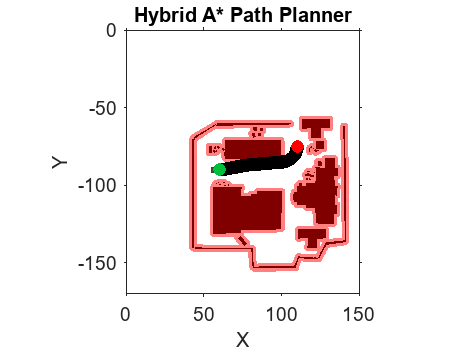

clear, close all
prj = currentProject;

map = Map();
map.loadMaps("main_scene_map_2d.mat");
planner = PathPlanner("Hybrid A* Planner", map);
startPose = [60, -90, 0];
goalPose = [110,-75,pi/2];
routeOriginal = planner.planPath(startPose, goalPose);

show(planner.planner)

### Case 1 - Small obstacle travel directly over without mitigation

First, set up map to include obstacle

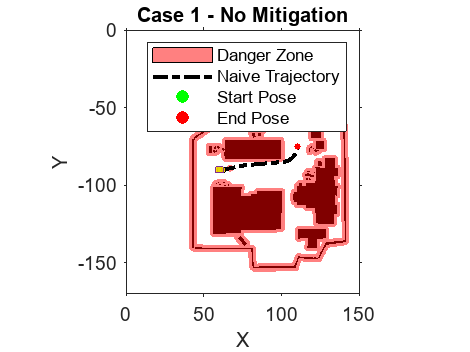

mapCase1 = Map();
mapCase1.loadMaps("main_scene_map_2d.mat");

obstacle1 = [67 -89];
mapCase1.BinaryMap.setOccupancy(obstacle1,1)
mapCase1.CostMap.setCosts(obstacle1,1)
plot(mapCase1.CostMap)
hold on
plot(routeOriginal.States(:,1),routeOriginal.States(:,2),'k-.',LineWidth=2)
scatter(startPose(1),startPose(2),8,'Marker','o','MarkerFaceColor','g','MarkerEdgeColor','g')
scatter(goalPose(1),goalPose(2),8,'Marker','o','MarkerFaceColor','r','MarkerEdgeColor','r')
hT = createVehicleGraphic(gca,startPose,"StartVehicle");
legend('Danger Zone','Naive Trajectory','Start Pose','End Pose')
title('Case 1 - No Mitigation')
exportgraphics(gca,"Case1.jpg")
hold off

% Save changes
save map1 mapCase1

### Case 2 - Small obstacle mitigate to pass over

Set up map to include obstacle

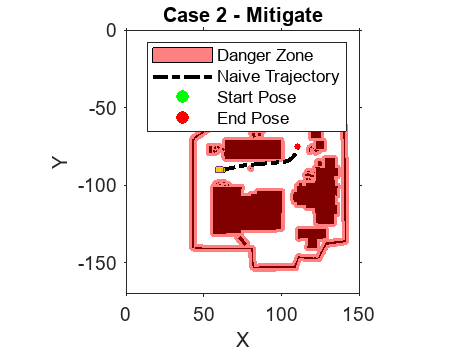

mapCase2 = Map();
mapCase2.loadMaps("main_scene_map_2d.mat");


obstacle2 = [80 -89.2];
mapCase2.BinaryMap.setOccupancy(obstacle2,1)
mapCase2.CostMap.setCosts(obstacle2,1)
plot(mapCase2.CostMap)
hold on
plot(routeOriginal.States(:,1),routeOriginal.States(:,2),'k-.',LineWidth=2)
scatter(startPose(1),startPose(2),8,'Marker','o','MarkerFaceColor','g','MarkerEdgeColor','g')
scatter(goalPose(1),goalPose(2),8,'Marker','o','MarkerFaceColor','r','MarkerEdgeColor','r')
hT = createVehicleGraphic(gca,startPose,"");
legend('Danger Zone','Naive Trajectory','Start Pose','End Pose')
title('Case 2 - Mitigate')
exportgraphics(gca,"Case2.jpg")
hold off

% Save changes
save map2 mapCase2

### Case 2b - Tight corner obstacle mitigation

Set up map to include obstacle

mapCase2b = Map();
mapCase2b.loadMaps("main_scene_map_2d.mat");


obstacle2b = [106 -86];
[k,d]=dsearchn(routeOriginal.States(:,1:2),obstacle2b)

k = 152

d = 2.5344

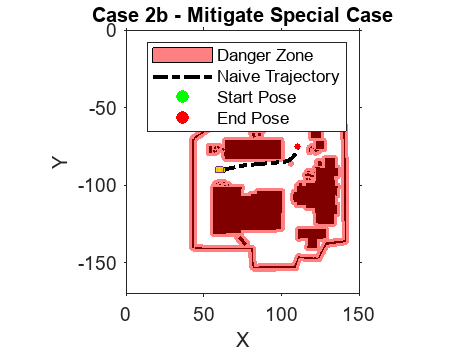

mapCase2b.BinaryMap.setOccupancy(obstacle2b,1)
mapCase2b.CostMap.setCosts(obstacle2b,1)
plot(mapCase2b.CostMap)
hold on
plot(routeOriginal.States(:,1),routeOriginal.States(:,2),'k-.',LineWidth=2)
scatter(startPose(1),startPose(2),8,'Marker','o','MarkerFaceColor','g','MarkerEdgeColor','g')
scatter(goalPose(1),goalPose(2),8,'Marker','o','MarkerFaceColor','r','MarkerEdgeColor','r')
hT = createVehicleGraphic(gca,startPose,"");
legend('Danger Zone','Naive Trajectory','Start Pose','End Pose')
title('Case 2b - Mitigate Special Case')
exportgraphics(gca,"Case2b.jpg")
hold off

% Save changes
save map2b mapCase2b

### Case 3 - Large obstacle mitigate to pass around

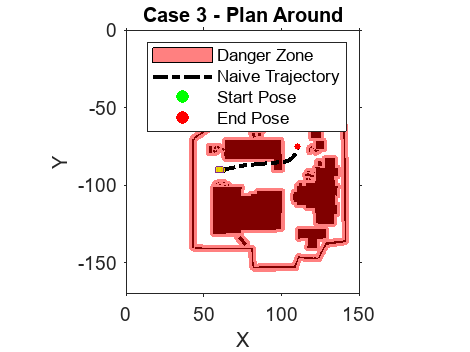

mapCase3 = Map();
mapCase3.loadMaps("main_scene_map_2d.mat");

xRange3 = linspace(95,100,50);
yRange3 = linspace(-80,-90,100);
[xx,yy] = meshgrid(xRange3,yRange3);
pts = [xx(:) yy(:)];
mapCase3.BinaryMap.setOccupancy(pts,1);
mapCase3.CostMap.setCosts(pts,1);
plot(mapCase3.CostMap)
hold on
plot(routeOriginal.States(:,1),routeOriginal.States(:,2),'k-.',LineWidth=2)
scatter(startPose(1),startPose(2),8,'Marker','o','MarkerFaceColor','g','MarkerEdgeColor','g')
scatter(goalPose(1),goalPose(2),8,'Marker','o','MarkerFaceColor','r','MarkerEdgeColor','r')
hT = createVehicleGraphic(gca,startPose,"");
legend('Danger Zone','Naive Trajectory','Start Pose','End Pose')
title('Case 3 - Plan Around')
exportgraphics(gca,"Case3.jpg")
hold off

save map3 mapCase3

### Case 4 - Large obstacle mitigate to back up and then pass around

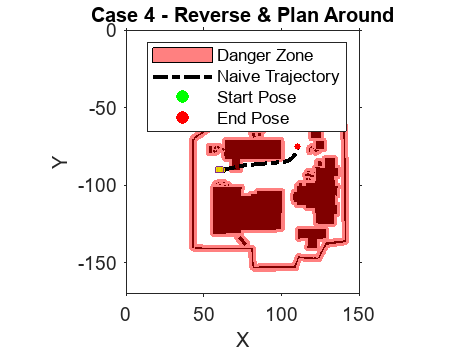

mapCase4 = Map();
mapCase4.loadMaps("main_scene_map_2d.mat");

xRange4 = linspace(68,73,50);
yRange4 = linspace(-80,-90,100);
[xx,yy] = meshgrid(xRange4,yRange4);
pts = [xx(:) yy(:)];
mapCase4.BinaryMap.setOccupancy(pts,1);
mapCase4.CostMap.setCosts(pts,1);
plot(mapCase4.CostMap)
hold on
plot(routeOriginal.States(:,1),routeOriginal.States(:,2),'k-.',LineWidth=2)
scatter(startPose(1),startPose(2),8,'Marker','o','MarkerFaceColor','g','MarkerEdgeColor','g')
scatter(goalPose(1),goalPose(2),8,'Marker','o','MarkerFaceColor','r','MarkerEdgeColor','r')
hT = createVehicleGraphic(gca,startPose,"");
legend('Danger Zone','Naive Trajectory','Start Pose','End Pose')
title('Case 4 - Reverse & Plan Around')
exportgraphics(gca,"Case4.jpg")
hold off

save map4 mapCase4

# Validate Maps

### Vehicle Definition

To keep consistent, we need to define our vehicle.

% Define Vehicle
vehicle.width = 5;
vehicle.length = 8;
vehicle.minTurningRadius = 10;
vehicle.startPose = startPose;
vehicle.goalPose = goalPose;

## Case 1 - No mitigation needed

First, lets initialize our stateflow chart by creating our obstacle and map objects

% Define Obstacle
obstacle.location = obstacle1;
obstacle.size = 0.25; % radius of obstacle

% Initialize chart
load("map1.mat");
chart = initializeChart(vehicle,obstacle,mapCase1,routeOriginal.States);

Then we run until we hit an end state and then plot

while chart.endStateReached == ""
    disp(chart.getActiveStates{1})
    chart.step
end

ObstacleDetected
Small_PlanOver


Plot our initial and final trajectories

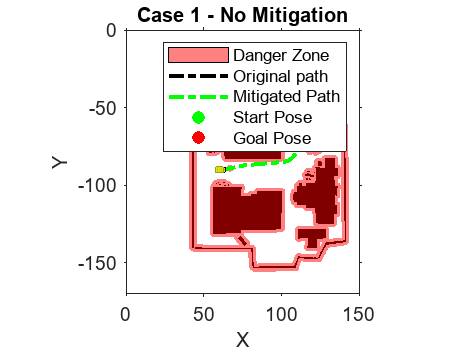

trajPlot(chart,mapCase1)

% animPlot(chart,mapCase1,'Case1.gif')

## Case 2 - Mitigation Needed

First, lets initialize our stateflow chart by creating our obstacle and map objects

% Define Obstacle
obstacle.location = obstacle2;
obstacle.size = 0.25; % radius of obstacle

% Initialize chart
load("map2.mat");
chart = initializeChart(vehicle,obstacle,mapCase2,routeOriginal.States);

Then we run until we hit an end state and then plot

while chart.endStateReached == ""
    disp(chart.getActiveStates{1})
    chart.step
end

ObstacleDetected
Small_PlanOver


Plot our initial and final trajectories

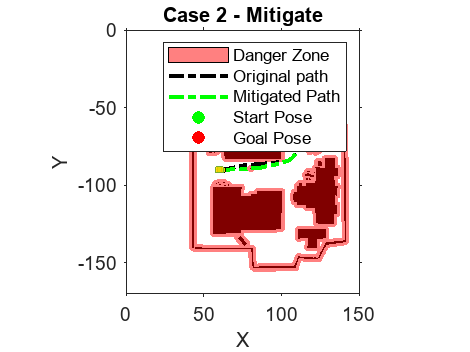

trajPlot(chart,mapCase2)

% animPlot(chart,mapCase2,'Case2.gif')

## Case 2b - Tight Corner Mitigation

First, lets initialize our stateflow chart by creating our obstacle and map objects

% Define Obstacle
obstacle.location = obstacle2b;
obstacle.size = 0.25; % radius of obstacle

% Initialize chart
load("map2b.mat");
chart = initializeChart(vehicle,obstacle,mapCase2b,routeOriginal.States);

Then we run until we hit an end state and then plot

while chart.endStateReached == ""
    disp(chart.getActiveStates{1})
    chart.step
end

ObstacleDetected
Small_PlanOver


Plot our initial and final trajectories

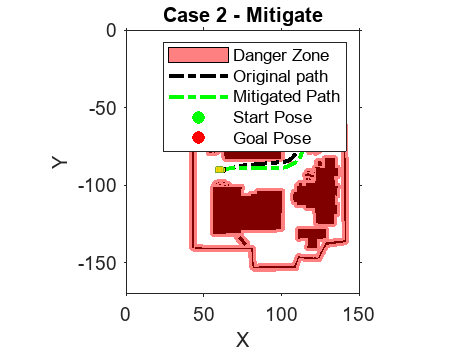

trajPlot(chart,mapCase2b)

% animPlot(chart,mapCase2b,'Case2b.gif')

## Case 3 - Large obstacle mitigate to pass around

First, lets initialize our stateflow chart by creating our obstacle and map objects

% Define Obstacle
obstacle.location = [xRange3(1),yRange3(1)]; % position of top corner
obstacle.size = 10; % size of obstacle facing vehicle

% Initialize chart
load("map3.mat");
chart = initializeChart(vehicle,obstacle,mapCase3,routeOriginal.States);

Then we run until we hit an end state and then plot

while chart.endStateReached == ""
    disp(chart.getActiveStates{1})
    chart.step
end

ObstacleDetected
Large_PlanAround


Plot our initial and final trajectories

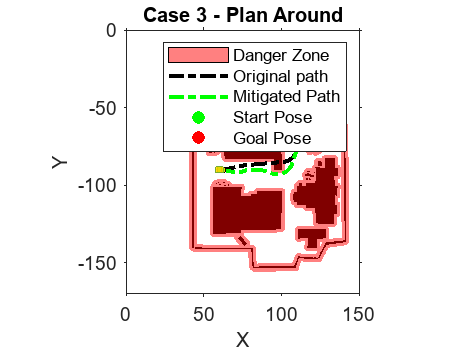

trajPlot(chart,mapCase3)

% animPlot(chart,mapCase3,'Case3.gif')

## Case 4 - Large obstacle mitigate to back up and then pass around

First, lets initialize our stateflow chart by creating our obstacle and map objects

% Define Obstacle
obstacle.location = [xRange4(1),yRange4(1)]; % position of top corner
obstacle.size = 10; % size of obstacle facing vehicle

% Initialize chart
load("map4.mat");
chart = initializeChart(vehicle,obstacle,mapCase4,routeOriginal.States);

Then we run until we hit an end state and then plot

while chart.endStateReached == ""
    disp(chart.getActiveStates{1})
    chart.step
end

ObstacleDetected
Large_PlanAround


Plot our initial and final trajectories

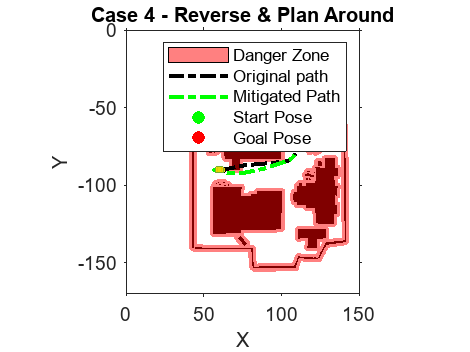

trajPlot(chart,mapCase4)

% animPlot(chart,mapCase4,'Case4.gif')

function trajPlot(chart,map)
    figure;
    plot(map.CostMap)
    hold on;
    plot(chart.trajectory(:,1),chart.trajectory(:,2),LineWidth=2,LineStyle='-.',Color='k')
    plot(chart.refPathOut(:,1),chart.refPathOut(:,2),LineWidth=2,LineStyle='-.',Color='g')
    scatter(chart.vehicle.startPose(1), chart.vehicle.startPose(2),8,'Marker','o','MarkerFaceColor','g','MarkerEdgeColor','g')
    scatter(chart.vehicle.goalPose(1),chart.vehicle.goalPose(2),8,'Marker','o','MarkerFaceColor','r','MarkerEdgeColor','r')
    hT = createVehicleGraphic(gca,chart.vehicle.startPose,"");
    hT = createVehicleGraphic(gca,chart.vehicle.goalPose,"GoalVehicle");
    legend('Danger Zone','Original path','Mitigated Path','Start Pose','Goal Pose')
    title(chart.endStateReached)
end
function chart = initializeChart(vehicle,obstacle,map,trajectory)
    chart = SmallObstacleMitigation_StateflowChart(obstacle=obstacle,vehicle=vehicle, ...
        planner=PathPlanner("Hybrid A* Planner", map),trajectory = trajectory, refPathOut=[0 0 0]);
    chart.Initialize;
end